# Synthesize a controller with a setteling time of 2 min. 

clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param.ctrl.T_ref = util.Celsius2Kelvin(20);
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);
%Wref
%lowpass filter wich result in a setling time of 10 min (600 sec) .  
s=tf('s');
wref =eye(4)*(1/(120*s+1));
wrefSS = ss(wref);
param.model.AWref = wrefSS.A; 
param.model.BWref = wrefSS.B;
param.model.CWref = wrefSS.C;
param.model.DWref = wrefSS.D;
%Wu set to 0 to not take u into the syntehsis procces
param.model.AWu = zeros(4); 
param.model.BWu = zeros(4);
param.model.CWu = zeros(4);
param.model.DWu = 0*eye(4);

## FWMM on SF

param.model.Dwz = 5*eye(4);
param = control.DesignProcedureFWMM(param,0);

Evaluation of design procedure for Frequency weighted model matching 
Gamma is found to be: 0.589177 


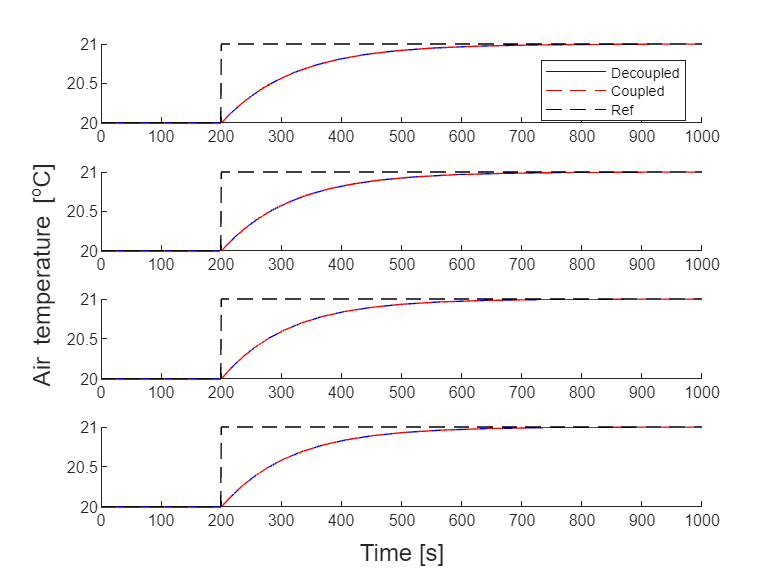

[resDeSF,resSF] = util.SimulateStep(param,"SimulateNonlinearStatefeedbackResults",0,1000);

info = stepinfo(resSF.Ta(:,1),resSF.time,util.Celsius2Kelvin(21),util.Celsius2Kelvin(20),'SettlingTimeThreshold',0.007);
fprintf('Settling time for SF is: %f \n', (info.SettlingTime - 200));

Settling time for SF is: 593.680626 


## FWMM on SOF

param.model.Dwz = 6*eye(4);
param = control.DesignProcedureSOF_ILMI_FWMM(param,0,{[-1,1]});

ans = NaN

ans = 1.3902

ans = 0.5052

ans = 0.2318

ans = 0.1465

ans = 0.1218

ans = 0.1121

ans = 0.1074

ans = 0.1048

ans = 0.1032

ans = 0.1022

ans = 0.1014

ans = 0.1009

ans = 0.1004

ans = 0.1000

ans = 0.0996

ans = 0.0993

ans = 0.0991

ans = 0.0988

ans = 0.0986

ans = 0.0984

ans = 0.0981

ans = 0.0979

ans = 0.0978

ans = 0.0976

ans = 0.0974

ans = 0.0973

ans = 0.0971

ans = 0.0969

ans = 0.0968

ans = 0.0967

ans = 0.0965

ans = 0.0964

ans = 0.0963

ans = 0.0962

ans = 0.0960

ans = 0.0959

ans = 0.0958

ans = 0.0956

ans = 0.0955

ans = 0.0954

ans = 0.0953

ans = 0.0952

ans = 0.0951

ans = 0.0949

ans = 0.0948

ans = 0.0947

ans = 0.0946

ans = 0.0945

ans = 0.0943

ans = 0.0942

ans = 0.0941

ans = 0.0940

ans = 0.0938

ans = 0.0937

ans = 0.0936

ans = 0.0935

ans = 0.0934

ans = 0.0932

ans = 0.0931

ans = 0.0930

ans = 0.0928

ans = 0.0927

ans = 0.0926

ans = 0.0924

ans = 0.0923

ans = 0.0922

ans = 0.0920

ans = 0.0919

ans = 0.0918

ans = 0.0916

ans = 0.0915

ans = 0.0913

ans = 0.0912

ans = 0.0910

ans = 0.0909

ans = 0.0907

ans = 0.0906

ans = 0.0904

ans = 0.0903

ans = 0.0901

ans = 0.0900

ans = 0.0898

ans = 0.0897

ans = 0.0895

ans = 0.0894

ans = 0.0892

ans = 0.0890

ans = 0.0889

ans = 0.0887

ans = 0.0885

ans = 0.0884

ans = 0.0882

ans = 0.0880

ans = 0.0878

ans = 0.0877

ans = 0.0875

ans = 0.0873

ans = 0.0871

ans = 0.0869

ans = 0.0867

ans = 0.0865

ans = 0.0863

ans = 0.0861

ans = 0.0859

ans = 0.0857

ans = 0.0855

ans = 0.0853

ans = 0.0851

ans = 0.0848

ans = 0.0846

ans = 0.0844

ans = 0.0842

ans = 0.0839

ans = 0.0837

ans = 0.0835

ans = 0.0832

ans = 0.0830

ans = 0.0827

ans = 0.0824

ans = 0.0822

ans = 0.0819

ans = 0.0816

ans = 0.0814

ans = 0.0811

ans = 0.0808

ans = 0.0805

ans = 0.0802

ans = 0.0799

ans = 0.0796

ans = 0.0793

ans = 0.0790

ans = 0.0787

ans = 0.0784

ans = 0.0781

ans = 0.0778

ans = 0.0774

ans = 0.0771

ans = 0.0767

ans = 0.0764

ans = 0.0760

ans = 0.0757

ans = 0.0753

ans = 0.0750

ans = 0.0746

ans = 0.0742

ans = 0.0739

ans = 0.0735

ans = 0.0731

ans = 0.0727

ans = 0.0723

ans = 0.0719

ans = 0.0715

ans = 0.0710

ans = 0.0706

ans = 0.0702

ans = 0.0697

ans = 0.0693

ans = 0.0689

ans = 0.0684

ans = 0.0680

ans = 0.0675

ans = 0.0670

ans = 0.0666

ans = 0.0661

ans = 0.0656

ans = 0.0651

ans = 0.0646

ans = 0.0641

ans = 0.0636

ans = 0.0631

ans = 0.0626

ans = 0.0621

ans = 0.0616

ans = 0.0611

ans = 0.0606

ans = 0.0601

ans = 0.0596

ans = 0.0591

ans = 0.0586

ans = 0.0582

ans = 0.0577

ans = 0.0572

ans = 0.0567

ans = 0.0562

ans = 0.0557

ans = 0.0553

ans = 0.0548

ans = 0.0544

ans = 0.0539

ans = 0.0535

ans = 0.0531

ans = 0.0527

ans = 0.0523

ans = 0.0519

ans = 0.0515

ans = 0.0512

ans = 0.0508

ans = 0.0505

ans = 0.0501

ans = 0.0498

ans = 0.0495

ans = 0.0492

ans = 0.0489

ans = 0.0486

ans = 0.0483

ans = 0.0480

ans = 0.0478

ans = 0.0475

ans = 0.0473

ans = 0.0470

ans = 0.0468

ans = 0.0465

ans = 0.0463

ans = 0.0461

ans = 0.0459

ans = 0.0457

ans = 0.0455

ans = 0.0453

ans = 0.0451

ans = 0.0449

ans = NaN

Alpha became NaN after 222 itr. Last value was 0.044884 


ans = 0.0452

ans = 0.0450

ans = 0.0448

ans = 0.0445

ans = 0.0443

ans = 0.0442

ans = 0.0440

ans = 0.0438

ans = 0.0436

ans = 0.0434

ans = 0.0433

ans = 0.0431

ans = 0.0430

ans = 0.0428

ans = 0.0426

ans = 0.0425

ans = 0.0424

ans = 0.0422

ans = 0.0421

ans = 0.0419

ans = 0.0418

ans = 0.0417

ans = 0.0415

ans = 0.0414

ans = 0.0413

ans = 0.0412

ans = 0.0410

ans = 0.0409

ans = 0.0408

ans = 0.0407

ans = 0.0406

ans = 0.0405

ans = 0.0404

ans = 0.0403

ans = 0.0402

ans = 0.0401

ans = 0.0400

ans = 0.0399

ans = 0.0398

ans = 0.0397

ans = 0.0396

ans = 0.0395

ans = 0.0394

ans = 0.0393

ans = 0.0392

ans = 0.0391

ans = 0.0390

ans = 0.0390

ans = 0.0389

ans = 0.0388

ans = 0.0387

ans = 0.0387

ans = 0.0386

ans = 0.0385

ans = 0.0384

ans = 0.0384

ans = 0.0383

ans = 0.0382

ans = 0.0381

ans = 0.0381

ans = 0.0380

ans = 0.0379

ans = 0.0379

ans = 0.0378

ans = 0.0377

ans = 0.0377

ans = 0.0376

ans = 0.0375

ans = 0.0375

ans = 0.0374

ans = 0.0374

ans = 0.0373

ans = 0.0373

ans = 0.0372

ans = 0.0372

ans = 0.0371

ans = 0.0370

ans = 0.0370

ans = 0.0369

ans = 0.0369

ans = 0.0368

ans = 0.0368

ans = 0.0367

ans = 0.0367

ans = 0.0366

ans = 0.0366

ans = 0.0365

ans = 0.0365

ans = 0.0364

ans = 0.0364

ans = 0.0363

ans = 0.0363

ans = 0.0363

ans = 0.0362

ans = 0.0362

ans = 0.0361

ans = 0.0361

ans = 0.0360

ans = 0.0360

ans = 0.0359

ans = 0.0359

ans = 0.0359

ans = 0.0358

ans = 0.0358

ans = 0.0358

ans = 0.0357

ans = 0.0357

ans = 0.0356

ans = 0.0356

ans = 0.0356

ans = 0.0355

ans = 0.0355

ans = 0.0355

ans = 0.0354

ans = 0.0354

ans = 0.0354

ans = 0.0353

ans = 0.0353

ans = 0.0353

ans = 0.0352

ans = 0.0352

ans = 0.0352

ans = 0.0351

ans = 0.0351

ans = 0.0351

ans = 0.0350

ans = 0.0350

ans = 0.0350

ans = 0.0350

ans = 0.0349

ans = 0.0349

ans = 0.0349

ans = 0.0349

ans = 0.0348

ans = 0.0348

ans = 0.0348

ans = 0.0347

ans = 0.0347

ans = 0.0347

ans = 0.0347

ans = 0.0346

ans = 0.0346

ans = 0.0346

ans = 0.0346

ans = 0.0345

ans = 0.0345

ans = 0.0345

ans = 0.0345

ans = 0.0345

ans = 0.0344

ans = 0.0344

ans = 0.0344

ans = 0.0344

ans = 0.0344

ans = 0.0343

ans = 0.0343

ans = 0.0343

ans = 0.0343

ans = 0.0342

ans = 0.0342

ans = 0.0342

ans = 0.0342

ans = 0.0342

ans = 0.0341

ans = 0.0341

ans = 0.0341

ans = 0.0341

ans = 0.0341

ans = 0.0340

ans = 0.0340

ans = 0.0340

ans = 0.0340

ans = 0.0339

ans = 0.0339

ans = 0.0339

ans = 0.0339

ans = 0.0339

ans = 0.0339

ans = 0.0338

ans = 0.0339

ans = 0.0338

ans = 0.0338

ans = 0.0338

ans = 0.0338

ans = 0.0338

ans = 0.0337

ans = 0.0337

ans = 0.0337

ans = 0.0337

ans = NaN

Alpha became NaN after 411 itr. Last value was 0.033669 


ans = 0.0338

ans = 0.0338

ans = 0.0337

ans = 0.0337

ans = 0.0337

ans = 0.0337

ans = 0.0336

ans = 0.0336

ans = 0.0336

ans = 0.0335

ans = 0.0335

ans = 0.0335

ans = 0.0335

ans = NaN

Alpha became NaN after 424 itr. Last value was 0.033470 


ans = 0.0336

ans = 0.0336

ans = 0.0335

ans = 0.0335

ans = 0.0334

ans = 0.0334

ans = 0.0334

ans = 0.0334

ans = 0.0333

ans = 0.0333

ans = 0.0333

ans = 0.0333

ans = 0.0332

ans = 0.0332

ans = 0.0332

ans = 0.0332

ans = NaN

Alpha became NaN after 440 itr. Last value was 0.033173 


ans = 0.0333

ans = 0.0333

ans = 0.0333

ans = 0.0332

ans = 0.0332

ans = 0.0331

ans = 0.0331

ans = 0.0331

ans = 0.0331

ans = 0.0330

ans = NaN

Alpha became NaN after 450 itr. Last value was 0.033035 


ans = 0.0332

ans = 0.0332

ans = 0.0331

ans = 0.0331

ans = 0.0330

ans = 0.0330

ans = 0.0329

ans = 0.0329

ans = 0.0329

ans = 0.0329

ans = 0.0328

ans = 0.0328

ans = 0.0328

ans = 0.0327

ans = 0.0327

ans = 0.0327

ans = 0.0327

ans = 0.0327

ans = 0.0326

ans = 0.0326

ans = 0.0326

ans = 0.0326

ans = 0.0326

ans = 0.0325

ans = 0.0325

ans = 0.0325

ans = 0.0325

ans = 0.0325

ans = 0.0324

ans = 0.0324

ans = 0.0324

ans = 0.0324

ans = 0.0323

ans = 0.0323

ans = NaN

Alpha became NaN after 484 itr. Last value was 0.032326 


ans = 0.0325

ans = 0.0324

ans = 0.0324

ans = NaN

Alpha became NaN after 487 itr. Last value was 0.032394 


ans = 0.0326

ans = 0.0325

ans = 0.0325

ans = 0.0324

ans = 0.0324

ans = 0.0323

ans = 0.0323

ans = 0.0323

ans = 0.0322

ans = 0.0322

ans = 0.0321

ans = 0.0321

ans = 0.0321

ans = 0.0321

ans = 0.0321

ans = 0.0320

ans = 0.0320

ans = 0.0320

ans = 0.0320

ans = NaN

Alpha became NaN after 506 itr. Last value was 0.031960 


ans = 0.0321

ans = 0.0321

ans = 0.0320

ans = 0.0320

ans = 0.0319

ans = NaN

Alpha became NaN after 511 itr. Last value was 0.031937 


ans = 0.0322

ans = 0.0321

ans = NaN

Alpha became NaN after 513 itr. Last value was 0.032074 


ans = 0.0324

ans = 0.0323

ans = 0.0322

ans = 0.0321

ans = 0.0320

ans = 0.0319

ans = 0.0319

ans = NaN

Alpha became NaN after 520 itr. Last value was 0.031891 


ans = 0.0321

ans = 0.0320

ans = 0.0320

ans = 0.0319

ans = 0.0319

ans = 0.0318

ans = 0.0318

ans = 0.0318

ans = 0.0317

ans = 0.0317

ans = 0.0316

ans = 0.0316

ans = 0.0316

ans = 0.0315

ans = 0.0315

ans = 0.0315

ans = NaN

Alpha became NaN after 536 itr. Last value was 0.031456 


ans = 0.0317

ans = 0.0316

ans = 0.0315

ans = 0.0315

ans = 0.0314

ans = 0.0314

ans = 0.0313

ans = 0.0313

ans = NaN

Alpha became NaN after 544 itr. Last value was 0.031319 


ans = 0.0315

ans = 0.0315

ans = 0.0314

ans = 0.0313

ans = 0.0313

ans = 0.0312

ans = 0.0312

ans = 0.0312

ans = NaN

Alpha became NaN after 552 itr. Last value was 0.031158 


ans = 0.0314

ans = 0.0313

ans = 0.0313

ans = 0.0312

ans = 0.0311

ans = 0.0311

ans = 0.0310

ans = 0.0310

ans = 0.0310

ans = 0.0309

ans = 0.0309

ans = 0.0309

ans = 0.0308

ans = 0.0308

ans = 0.0307

ans = 0.0307

ans = 0.0307

ans = 0.0306

ans = NaN

Alpha became NaN after 570 itr. Last value was 0.030640 


ans = 0.0308

ans = 0.0308

ans = 0.0307

ans = 0.0306

ans = 0.0306

ans = 0.0306

ans = 0.0305

ans = 0.0305

ans = 0.0304

ans = NaN

Alpha became NaN after 579 itr. Last value was 0.030449 


ans = 0.0307

ans = 0.0306

ans = 0.0305

ans = 0.0305

ans = 0.0304

ans = 0.0304

ans = NaN

Alpha became NaN after 585 itr. Last value was 0.030388 


ans = 0.0306

ans = 0.0305

ans = 0.0305

ans = 0.0304

ans = 0.0304

ans = 0.0303

ans = NaN

Alpha became NaN after 591 itr. Last value was 0.030319 


ans = 0.0306

ans = 0.0305

ans = 0.0304

ans = 0.0303

ans = 0.0303

ans = 0.0302

ans = NaN

Alpha became NaN after 597 itr. Last value was 0.030205 


ans = 0.0305

ans = 0.0304

ans = 0.0303

ans = 0.0302

ans = NaN

Alpha became NaN after 601 itr. Last value was 0.030228 


ans = 0.0305

ans = 0.0304

ans = 0.0303

ans = 0.0302

ans = 0.0301

ans = 0.0301

ans = 0.0300

ans = 0.0300

ans = 0.0299

ans = 0.0298

ans = 0.0298

ans = 0.0297

ans = 0.0297

ans = 0.0296

ans = 0.0296

ans = 0.0295

ans = 0.0295

ans = 0.0295

ans = 0.0294

ans = 0.0294

ans = 0.0293

ans = 0.0293

ans = NaN

Alpha became NaN after 623 itr. Last value was 0.029297 


ans = 0.0295

ans = 0.0294

ans = 0.0293

ans = 0.0293

ans = 0.0293

ans = 0.0292

ans = 0.0292

ans = 0.0291

ans = 0.0291

ans = 0.0290

ans = 0.0290

ans = 0.0290

ans = 0.0289

ans = 0.0289

ans = 0.0288

ans = 0.0288

ans = NaN

Alpha became NaN after 639 itr. Last value was 0.028801 


ans = 0.0290

ans = 0.0289

ans = 0.0289

ans = NaN

Alpha became NaN after 642 itr. Last value was 0.028862 


ans = 0.0291

ans = 0.0290

ans = 0.0289

ans = 0.0289

ans = 0.0288

ans = 0.0288

ans = 0.0287

ans = 0.0287

ans = 0.0286

ans = 0.0286

ans = 0.0285

ans = 0.0285

ans = 0.0284

ans = 0.0284

ans = 0.0283

ans = 0.0283

ans = 0.0283

ans = 0.0282

ans = 0.0282

ans = 0.0281

ans = 0.0281

ans = 0.0281

ans = 0.0280

ans = NaN

Alpha became NaN after 665 itr. Last value was 0.028030 


ans = 0.0282

ans = 0.0281

ans = 0.0281

ans = 0.0280

ans = 0.0280

ans = 0.0280

ans = 0.0279

ans = 0.0279

ans = 0.0278

ans = 0.0278

ans = 0.0277

ans = NaN

Alpha became NaN after 676 itr. Last value was 0.027733 


ans = 0.0279

ans = 0.0278

ans = 0.0278

ans = 0.0277

ans = 0.0277

ans = 0.0276

ans = 0.0276

ans = 0.0275

ans = 0.0275

ans = 0.0275

ans = 0.0274

ans = 0.0274

ans = 0.0274

ans = 0.0273

ans = 0.0273

ans = 0.0272

ans = 0.0272

ans = 0.0272

ans = 0.0271

ans = 0.0271

ans = 0.0271

ans = 0.0270

ans = 0.0270

ans = 0.0270

ans = 0.0269

ans = 0.0269

ans = NaN

Alpha became NaN after 702 itr. Last value was 0.026924 


ans = 0.0271

ans = 0.0270

ans = 0.0270

ans = 0.0269

ans = NaN

Alpha became NaN after 706 itr. Last value was 0.026924 


ans = 0.0271

ans = 0.0270

ans = 0.0270

ans = 0.0269

ans = 0.0269

ans = 0.0268

ans = 0.0268

ans = 0.0267

ans = 0.0267

ans = 0.0266

ans = 0.0266

ans = 0.0266

ans = NaN

Alpha became NaN after 718 itr. Last value was 0.026566 


ans = 0.0267

ans = 0.0267

ans = 0.0266

ans = 0.0266

ans = 0.0265

ans = 0.0265

ans = 0.0264

ans = 0.0264

ans = 0.0264

ans = 0.0263

ans = 0.0263

ans = 0.0262

ans = 0.0262

ans = 0.0262

ans = 0.0261

ans = 0.0261

ans = 0.0261

ans = 0.0260

ans = 0.0260

ans = 0.0260

ans = 0.0259

ans = 0.0259

ans = 0.0259

ans = 0.0258

ans = 0.0258

ans = 0.0258

ans = 0.0257

ans = 0.0257

ans = 0.0257

ans = 0.0257

ans = 0.0256

ans = 0.0256

ans = NaN

Alpha became NaN after 750 itr. Last value was 0.025604 


ans = 0.0257

ans = 0.0257

ans = 0.0256

ans = 0.0256

ans = 0.0255

ans = 0.0255

ans = 0.0255

ans = 0.0254

ans = 0.0254

ans = 0.0254

ans = 0.0253

ans = 0.0253

ans = 0.0253

ans = 0.0253

ans = 0.0252

ans = 0.0252

ans = 0.0252

ans = 0.0251

ans = NaN

Alpha became NaN after 768 itr. Last value was 0.025139 


ans = 0.0253

ans = 0.0252

ans = 0.0252

ans = 0.0251

ans = 0.0251

ans = 0.0250

ans = NaN

Alpha became NaN after 774 itr. Last value was 0.025040 


ans = 0.0252

ans = 0.0251

ans = 0.0251

ans = 0.0250

ans = 0.0250

ans = 0.0249

ans = 0.0249

ans = 0.0249

ans = 0.0248

ans = 0.0248

ans = 0.0248

ans = 0.0247

ans = 0.0247

ans = 0.0247

ans = 0.0246

ans = 0.0246

ans = 0.0246

ans = 0.0245

ans = 0.0245

ans = 0.0245

ans = 0.0244

ans = 0.0244

ans = 0.0244

ans = NaN

Alpha became NaN after 797 itr. Last value was 0.024391 


ans = 0.0245

ans = 0.0244

ans = 0.0244

ans = 0.0244

ans = 0.0243

ans = 0.0243

ans = 0.0243

ans = 0.0242

ans = 0.0242

ans = 0.0242

ans = 0.0241

ans = 0.0241

ans = 0.0241

ans = 0.0240

ans = 0.0240

ans = 0.0240

ans = 0.0239

ans = 0.0239

ans = 0.0239

ans = 0.0239

ans = 0.0238

ans = 0.0238

ans = 0.0238

ans = 0.0238

ans = 0.0237

ans = 0.0237

ans = 0.0237

ans = 0.0237

ans = 0.0236

ans = 0.0236

ans = 0.0236

ans = 0.0236

ans = 0.0235

ans = 0.0235

ans = 0.0235

ans = 0.0235

ans = 0.0234

ans = 0.0234

ans = 0.0234

ans = 0.0234

ans = NaN

Alpha became NaN after 837 itr. Last value was 0.023384 


ans = 0.0235

ans = 0.0234

ans = 0.0234

ans = 0.0233

ans = 0.0233

ans = 0.0233

ans = 0.0232

ans = 0.0232

ans = 0.0232

ans = 0.0232

ans = 0.0231

ans = 0.0231

ans = 0.0231

ans = 0.0231

ans = 0.0230

ans = 0.0230

ans = 0.0230

ans = 0.0230

ans = 0.0229

ans = 0.0229

ans = 0.0229

ans = 0.0229

ans = NaN

Alpha became NaN after 859 itr. Last value was 0.022865 


ans = 0.0229

ans = 0.0229

ans = 0.0229

ans = 0.0228

ans = 0.0228

ans = 0.0228

ans = 0.0227

ans = 0.0227

ans = 0.0227

ans = 0.0227

ans = 0.0226

ans = 0.0226

ans = 0.0226

ans = 0.0225

ans = 0.0225

ans = 0.0225

ans = NaN

Alpha became NaN after 875 itr. Last value was 0.022491 


ans = 0.0226

ans = 0.0225

ans = 0.0225

ans = 0.0225

ans = 0.0224

ans = 0.0224

ans = NaN

Alpha became NaN after 881 itr. Last value was 0.022385 


ans = 0.0225

ans = 0.0225

ans = 0.0224

ans = 0.0223

ans = 0.0223

ans = 0.0223

ans = 0.0222

ans = 0.0222

ans = 0.0221

ans = 0.0221

ans = NaN

Alpha became NaN after 891 itr. Last value was 0.022118 


ans = 0.0222

ans = 0.0222

ans = 0.0221

ans = 0.0221

ans = 0.0220

ans = 0.0220

ans = 0.0220

ans = 0.0219

ans = 0.0219

ans = 0.0219

ans = 0.0218

ans = NaN

Alpha became NaN after 902 itr. Last value was 0.021820 


ans = 0.0219

ans = 0.0219

ans = 0.0218

ans = 0.0218

ans = 0.0217

ans = 0.0217

ans = 0.0217

ans = 0.0216

ans = 0.0216

ans = 0.0216

ans = 0.0215

ans = 0.0215

ans = 0.0215

ans = 0.0214

ans = 0.0214

ans = 0.0214

ans = 0.0213

ans = 0.0213

ans = 0.0213

ans = 0.0212

ans = 0.0212

ans = 0.0212

ans = 0.0211

ans = 0.0211

ans = 0.0211

ans = 0.0211

ans = 0.0210

ans = 0.0210

ans = 0.0210

ans = 0.0210

ans = 0.0209

ans = 0.0209

ans = 0.0209

ans = 0.0209

ans = 0.0208

ans = 0.0208

ans = 0.0208

ans = 0.0208

ans = 0.0207

ans = 0.0207

ans = 0.0207

ans = 0.0207

ans = NaN

Alpha became NaN after 944 itr. Last value was 0.020653 


ans = 0.0207

ans = 0.0207

ans = 0.0206

ans = 0.0206

ans = 0.0206

ans = 0.0205

ans = 0.0205

ans = 0.0205

ans = 0.0204

ans = 0.0204

ans = NaN

Alpha became NaN after 954 itr. Last value was 0.020401 


ans = 0.0205

ans = 0.0204

ans = 0.0204

ans = 0.0203

ans = 0.0203

ans = 0.0203

ans = 0.0202

ans = 0.0202

ans = 0.0202

ans = 0.0201

ans = 0.0201

ans = 0.0201

ans = 0.0201

ans = 0.0200

ans = 0.0200

ans = 0.0200

ans = 0.0199

ans = 0.0199

ans = 0.0199

ans = 0.0199

ans = 0.0198

ans = 0.0198

ans = 0.0198

ans = 0.0198

ans = 0.0197

ans = 0.0197

ans = 0.0197

ans = 0.0196

ans = 0.0196

ans = 0.0196

ans = 0.0196

ans = 0.0195

ans = 0.0195

ans = 0.0195

ans = 0.0195

ans = 0.0194

ans = 0.0194

ans = 0.0194

ans = 0.0194

ans = 0.0193

ans = 0.0193

ans = 0.0193

ans = 0.0193

ans = 0.0192

ans = 0.0192

ans = 0.0192

ans = 0.0192

ans = 0.0191

ans = 0.0191

ans = 0.0191

ans = 0.0191

ans = 0.0191

ans = 0.0190

ans = 0.0190

ans = 0.0190

ans = 0.0190

ans = 0.0189

ans = 0.0189

ans = 0.0189

ans = 0.0189

ans = 0.0188

ans = 0.0188

ans = 0.0188

ans = 0.0188

ans = 0.0187

ans = 0.0187

ans = 0.0187

ans = 0.0187

ans = 0.0186

ans = 0.0186

ans = 0.0186

ans = 0.0186

ans = 0.0185

ans = 0.0185

ans = 0.0185

ans = 0.0185

ans = 0.0184

ans = 0.0184

ans = 0.0184

ans = 0.0184

ans = 0.0183

ans = 0.0183

ans = 0.0183

ans = 0.0183

ans = 0.0182

ans = 0.0182

ans = NaN

Alpha became NaN after 1040 itr. Last value was 0.018227 


ans = 0.0183

ans = 0.0182

ans = 0.0182

ans = 0.0182

ans = 0.0181

ans = 0.0181

ans = 0.0181

ans = 0.0180

ans = 0.0180

ans = 0.0180

ans = 0.0179

ans = 0.0179

ans = 0.0179

ans = 0.0179

ans = 0.0178

ans = 0.0178

ans = 0.0178

ans = 0.0177

ans = 0.0177

ans = 0.0177

ans = 0.0177

ans = 0.0176

ans = 0.0176

ans = 0.0176

ans = 0.0176

ans = 0.0175

ans = 0.0175

ans = 0.0175

ans = 0.0175

ans = 0.0174

ans = 0.0174

ans = 0.0174

ans = 0.0174

ans = 0.0173

ans = 0.0173

ans = 0.0173

ans = 0.0173

ans = 0.0172

ans = 0.0172

ans = 0.0172

ans = 0.0172

ans = 0.0171

ans = 0.0171

ans = 0.0171

ans = 0.0171

ans = 0.0170

ans = 0.0170

ans = 0.0170

ans = 0.0170

ans = 0.0169

ans = 0.0169

ans = 0.0169

ans = 0.0169

ans = 0.0168

ans = 0.0168

ans = 0.0168

ans = 0.0168

ans = 0.0167

ans = 0.0167

ans = 0.0167

ans = 0.0167

ans = 0.0166

ans = 0.0166

ans = 0.0166

ans = 0.0166

ans = 0.0165

ans = 0.0165

ans = 0.0165

ans = 0.0165

ans = 0.0164

ans = 0.0164

ans = 0.0164

ans = 0.0164

ans = 0.0163

ans = 0.0163

ans = 0.0163

ans = 0.0163

ans = 0.0163

ans = 0.0162

ans = 0.0162

ans = NaN

Alpha became NaN after 1120 itr. Last value was 0.016197 


ans = 0.0162

ans = 0.0162

ans = 0.0161

ans = 0.0161

ans = 0.0161

ans = 0.0160

ans = 0.0160

ans = 0.0160

ans = 0.0159

ans = 0.0159

ans = 0.0159

ans = 0.0159

ans = 0.0158

ans = 0.0158

ans = 0.0158

ans = 0.0157

ans = 0.0157

ans = 0.0157

ans = 0.0157

ans = 0.0156

ans = 0.0156

ans = 0.0156

ans = 0.0156

ans = NaN

Alpha became NaN after 1143 itr. Last value was 0.015564 


ans = 0.0156

ans = 0.0156

ans = NaN

Alpha became NaN after 1145 itr. Last value was 0.015564 


ans = 0.0157

ans = 0.0156

ans = 0.0155

ans = 0.0155

ans = 0.0154

ans = 0.0154

ans = 0.0153

ans = 0.0153

ans = 0.0152

ans = 0.0152

ans = 0.0152

ans = 0.0151

ans = 0.0151

ans = 0.0151

ans = 0.0150

ans = 0.0150

ans = 0.0150

ans = 0.0149

ans = 0.0149

ans = 0.0149

ans = 0.0149

ans = 0.0148

ans = 0.0148

ans = 0.0148

ans = 0.0147

ans = 0.0147

ans = 0.0147

ans = 0.0147

ans = NaN

Alpha became NaN after 1173 itr. Last value was 0.014656 


ans = 0.0147

ans = 0.0146

ans = 0.0146

ans = NaN

Alpha became NaN after 1176 itr. Last value was 0.014595 


ans = 0.0147

ans = 0.0146

ans = 0.0145

ans = 0.0145

ans = 0.0144

ans = 0.0144

ans = 0.0143

ans = 0.0143

ans = 0.0143

ans = 0.0142

ans = 0.0142

ans = 0.0142

ans = 0.0141

ans = 0.0141

ans = 0.0141

ans = 0.0140

ans = 0.0140

ans = 0.0140

ans = 0.0139

ans = 0.0139

ans = 0.0139

ans = 0.0139

ans = 0.0138

ans = 0.0138

ans = 0.0138

ans = 0.0137

ans = 0.0137

ans = 0.0137

ans = 0.0137

ans = 0.0136

ans = 0.0136

ans = 0.0136

ans = 0.0135

ans = 0.0135

ans = 0.0135

ans = 0.0135

ans = 0.0134

ans = 0.0134

ans = 0.0134

ans = 0.0133

ans = 0.0133

ans = 0.0133

ans = 0.0133

ans = 0.0132

ans = 0.0132

ans = 0.0132

ans = 0.0131

ans = 0.0131

ans = NaN

Alpha became NaN after 1224 itr. Last value was 0.013115 


ans = NaN

Alpha became NaN after 1224 itr. Last value was 0.023115 


ans = 0.0131

ans = 0.0131

ans = 0.0130

ans = NaN

Alpha became NaN after 1227 itr. Last value was 0.013016 


ans = 0.0132

ans = NaN

Alpha became NaN after 1228 itr. Last value was 0.013153 


ans = 0.0134

ans = 0.0132

ans = 0.0131

ans = 0.0130

ans = 0.0129

ans = 0.0128

ans = 0.0127

ans = 0.0127

ans = 0.0126

ans = 0.0126

ans = 0.0125

ans = 0.0125

ans = 0.0125

ans = 0.0124

ans = 0.0124

ans = 0.0124

ans = 0.0123

ans = NaN

Alpha became NaN after 1245 itr. Last value was 0.012314 


ans = 0.0124

ans = 0.0123

ans = 0.0122

ans = 0.0122

ans = NaN

Alpha became NaN after 1249 itr. Last value was 0.012184 


ans = 0.0123

ans = 0.0122

ans = NaN

Alpha became NaN after 1251 itr. Last value was 0.012207 


ans = 0.0124

ans = 0.0123

ans = 0.0121

ans = 0.0121

ans = 0.0120

ans = 0.0119

ans = 0.0118

ans = 0.0118

ans = 0.0117

ans = 0.0117

ans = 0.0116

ans = 0.0116

ans = 0.0115

ans = 0.0115

ans = 0.0115

ans = 0.0114

ans = 0.0114

ans = 0.0113

ans = NaN

Alpha became NaN after 1269 itr. Last value was 0.011345 


ans = 0.0114

ans = 0.0113

ans = 0.0113

ans = 0.0112

ans = 0.0112

ans = 0.0111

ans = NaN

Alpha became NaN after 1275 itr. Last value was 0.011116 


ans = 0.0112

ans = 0.0111

ans = 0.0110

ans = 0.0110

ans = 0.0109

ans = 0.0109

ans = 0.0108

ans = 0.0108

ans = 0.0107

ans = 0.0107

ans = 0.0107

ans = 0.0106

ans = 0.0106

ans = 0.0105

ans = 0.0105

ans = 0.0105

ans = NaN

Alpha became NaN after 1291 itr. Last value was 0.010475 


ans = 0.0105

ans = 0.0104

ans = 0.0104

ans = NaN

Alpha became NaN after 1294 itr. Last value was 0.010376 


ans = 0.0105

ans = 0.0104

ans = 0.0103

ans = 0.0102

ans = 0.0102

ans = 0.0101

ans = 0.0101

ans = NaN

Alpha became NaN after 1301 itr. Last value was 0.010063 


ans = 0.0102

ans = 0.0101

ans = 0.0100

ans = NaN

Alpha became NaN after 1304 itr. Last value was 0.009979 


ans = 0.0101

ans = 0.0100

ans = 0.0099

ans = 0.0098

ans = NaN

Alpha became NaN after 1308 itr. Last value was 0.009819 


ans = 0.0100

ans = 0.0098

ans = 0.0097

ans = 0.0096

ans = 0.0096

ans = 0.0095

ans = 0.0094

ans = 0.0093

ans = 0.0093

ans = 0.0092

ans = 0.0092

ans = 0.0091

ans = 0.0091

ans = 0.0090

ans = NaN

Alpha became NaN after 1322 itr. Last value was 0.009041 


ans = 0.0091

ans = 0.0090

ans = 0.0089

ans = 0.0089

ans = 0.0088

ans = 0.0088

ans = 0.0087

ans = 0.0087

ans = 0.0086

ans = 0.0086

ans = 0.0085

ans = 0.0085

ans = 0.0085

ans = 0.0084

ans = 0.0084

ans = 0.0083

ans = NaN

Alpha became NaN after 1338 itr. Last value was 0.008324 


ans = 0.0084

ans = 0.0083

ans = 0.0082

ans = 0.0082

ans = 0.0081

ans = 0.0080

ans = 0.0080

ans = 0.0080

ans = 0.0079

ans = 0.0079

ans = 0.0078

ans = 0.0078

ans = 0.0077

ans = NaN

Alpha became NaN after 1351 itr. Last value was 0.007736 


ans = 0.0078

ans = 0.0077

ans = 0.0076

ans = NaN

Alpha became NaN after 1354 itr. Last value was 0.007614 


ans = 0.0077

ans = 0.0076

ans = 0.0075

ans = 0.0074

ans = 0.0073

ans = 0.0073

ans = 0.0072

ans = 0.0072

ans = 0.0071

ans = 0.0071

ans = 0.0070

ans = NaN

Alpha became NaN after 1365 itr. Last value was 0.007034 


ans = 0.0071

ans = 0.0070

ans = 0.0069

ans = 0.0068

ans = 0.0068

ans = 0.0067

ans = 0.0067

ans = 0.0066

ans = 0.0066

ans = NaN

Alpha became NaN after 1374 itr. Last value was 0.006577 


ans = 0.0066

ans = 0.0065

ans = NaN

Alpha became NaN after 1376 itr. Last value was 0.006523 


ans = 0.0066

ans = 0.0065

ans = 0.0064

ans = 0.0063

ans = 0.0062

ans = 0.0061

ans = 0.0061

ans = 0.0060

ans = 0.0060

ans = 0.0059

ans = 0.0059

ans = 0.0058

ans = 0.0057

ans = 0.0057

ans = 0.0056

ans = 0.0056

ans = 0.0055

ans = 0.0055

ans = 0.0054

ans = 0.0054

ans = 0.0053

ans = 0.0053

ans = 0.0052

ans = 0.0052

ans = 0.0051

ans = 0.0051

ans = 0.0050

ans = 0.0050

ans = 0.0049

ans = 0.0049

ans = 0.0048

ans = NaN

Alpha became NaN after 1407 itr. Last value was 0.004829 


ans = 0.0048

ans = NaN

Alpha became NaN after 1408 itr. Last value was 0.004829 


ans = 0.0050

ans = 0.0048

ans = 0.0046

ans = 0.0046

ans = 0.0045

ans = 0.0044

ans = NaN

Alpha became NaN after 1414 itr. Last value was 0.004410 


ans = 0.0045

ans = 0.0043

ans = 0.0042

ans = 0.0042

ans = 0.0041

ans = 0.0040

ans = 0.0040

ans = 0.0039

ans = 0.0039

ans = 0.0038

ans = 0.0037

ans = 0.0037

ans = NaN

Alpha became NaN after 1426 itr. Last value was 0.003677 


ans = NaN

Alpha became NaN after 1426 itr. Last value was 0.013677 


ans = 0.0036

ans = 0.0035

ans = NaN

Alpha became NaN after 1428 itr. Last value was 0.003525 


ans = 0.0036

ans = 0.0034

ans = NaN

Alpha became NaN after 1430 itr. Last value was 0.003426 


ans = 0.0035

ans = 0.0033

ans = NaN

Alpha became NaN after 1432 itr. Last value was 0.003326 


ans = NaN

Alpha became NaN after 1432 itr. Last value was 0.013326 


ans = NaN

Alpha became NaN after 1432 itr. Last value was 0.023326 


ans = 0.0035

ans = NaN

Alpha became NaN after 1433 itr. Last value was 0.003479 


ans = 0.0037

ans = 0.0032

ans = NaN

Alpha became NaN after 1435 itr. Last value was 0.003197 


ans = 0.0033

ans = 0.0030

ans = 0.0027

ans = 0.0025

ans = NaN

Alpha became NaN after 1439 itr. Last value was 0.002457 


ans = 0.0026

ans = 0.0023

ans = 0.0021

ans = 0.0020

ans = 0.0019

ans = 0.0018

ans = 0.0017

ans = 0.0016

ans = 0.0016

ans = 0.0015

ans = 0.0014

ans = 0.0013

ans = 0.0013

ans = 0.0012

ans = NaN

Alpha became NaN after 1453 itr. Last value was 0.001183 


ans = 0.0012

ans = 0.0011

ans = 9.5367e-04

Elapsed time is 8711.437984 seconds.
Took 1455 iterations 
Evaluation of design procedure for ILMI SOF 
Gamma is found to be: 1.000000 
Eigenvalues of the decoupled systems are all negative 


ans =    -3.8948   -0.1347   -0.0075   -3.8848   -0.1828   -0.0078   -3.7806   -0.2485   -0.0079   -3.8191   -0.2098   -0.0079


Eigenvalues of the coupled systems are all negative 


ans =    -3.7703   -3.6773   -3.5833   -3.4302   -0.5986   -0.2607   -0.3787   -0.4536   -0.0082   -0.0084   -0.0085   -0.0085


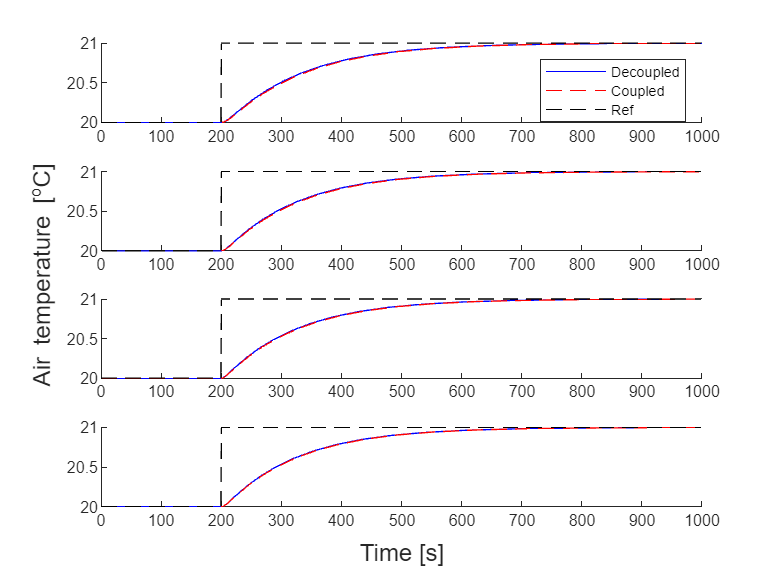

% % % % save('SOF_Performance2.mat','param')
% % % % % % save('SOF_Performance.mat','param')
% load('SOF_Performance.mat')
[resDeSoF,resSOF] = util.SimulateStep(param,"SimulateNonlinearSOFResults",0,1000);

info = stepinfo(resSOF.Ta(:,1),resSOF.time,util.Celsius2Kelvin(21),util.Celsius2Kelvin(20),'SettlingTimeThreshold',0.007);
fprintf('Settling time for SOF is: %f \n', (info.SettlingTime - 200));

Settling time for SOF is: 637.222291 


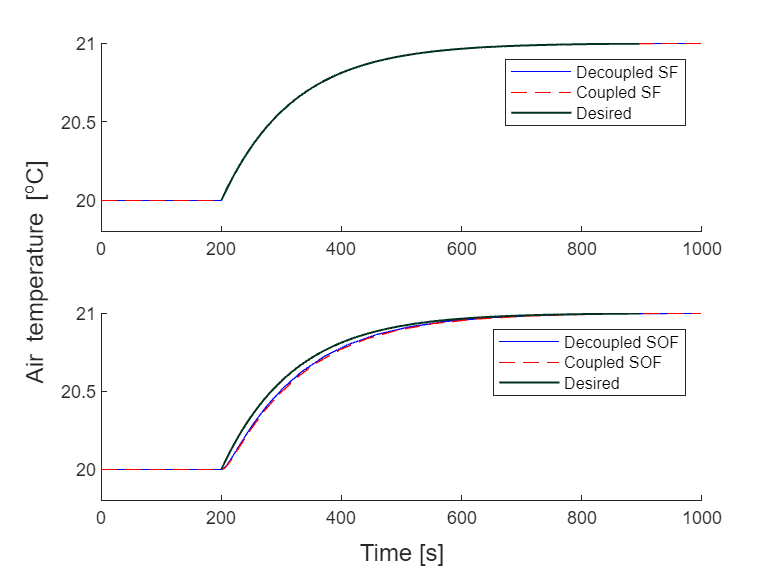


util.CompareDesired(param,'CompareDesired',resDeSF,resSF,resDeSoF,resSOF);

# Synthesize a controller with a setteling time of 2 min. 

### Initizilation

clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param.ctrl.T_ref = util.Celsius2Kelvin(20);
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);
%Wref
%lowpass filter wich result in a setling time of 2 min (120 sec) .  
s=tf('s');
wref =eye(4)*(1/(24*s+1));
wrefSS = ss(wref);
param.model.AWref = wrefSS.A; 
param.model.BWref = wrefSS.B;
param.model.CWref = wrefSS.C;
param.model.DWref = wrefSS.D;

%Wu set to 0 to not take u into the syntehsis procces
param.model.AWu = zeros(4); 
param.model.BWu = zeros(4);
param.model.CWu = zeros(4);
param.model.DWu = 0*eye(4);

## FWMM on SF

param.model.Dwz = 20*eye(4);
param = control.DesignProcedureFWMM(param,0);

Evaluation of design procedure for Frequency weighted model matching 
Gamma is found to be: 0.591719 


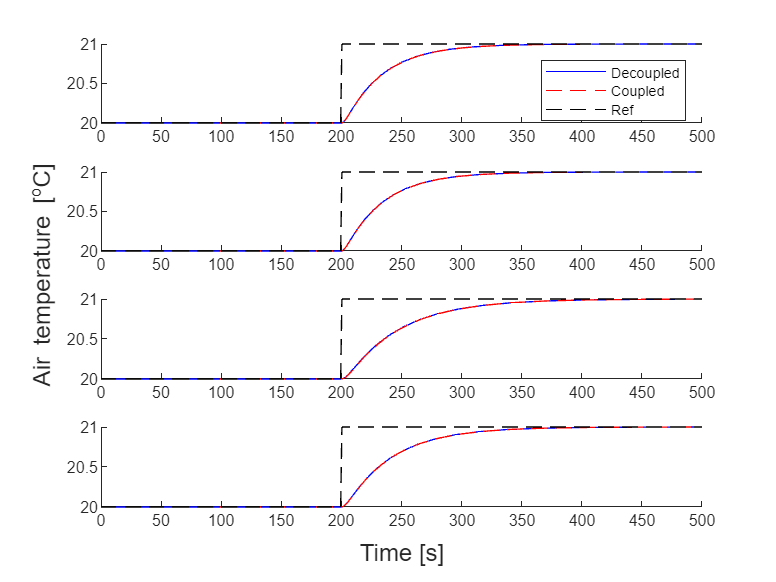

[~,res] = util.SimulateStep(param,"SimulateNonlinearStatefeedbackResults_2_min",0,500);

info = stepinfo(res.Ta(:,1),res.time,util.Celsius2Kelvin(21),util.Celsius2Kelvin(20),'SettlingTimeThreshold',0.007);
fprintf('Settling time for SF is: %f \n', (info.SettlingTime - 200));

Settling time for SF is: 164.082519 


Attempt with polytopic uncertainties

param = control.DesingProcedureFWMM_Polytopic(param,0,{[-1,1]});

Evaluation of design procedure for Frequency weighted model matching with polytopic uncertainties
Gamma is found to be: 0.000195 


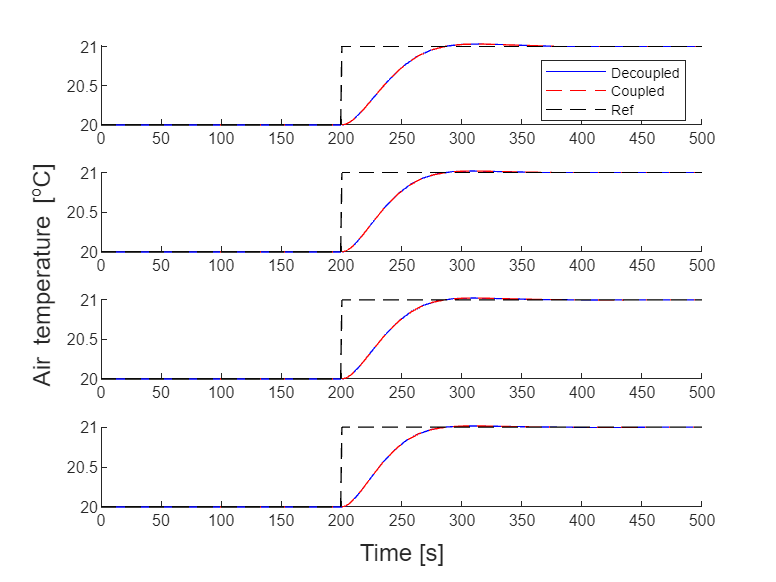

figure()
[~,res] = util.SimulateStep(param,"SimulateNonlinearStatefeedbackResults_2_min",0,500);

info = stepinfo(res.Ta(:,1),res.time,util.Celsius2Kelvin(21),util.Celsius2Kelvin(20),'SettlingTimeThreshold',0.007);
fprintf('Settling time for SF is: %f \n', (info.SettlingTime - 200));

Settling time for SF is: 169.023594 


## FWMM on SOF

param.model.Dwz = 5*eye(4);
param = control.DesignProcedureSOF_ILMI_FWMM(param,0,{[-1,1]});

ans = 31.3124

ans = 1.2102

ans = 0.4648

ans = 0.2694

ans = 0.2090

ans = 0.1780

ans = 0.1584

ans = 0.1449

ans = 0.1349

ans = 0.1268

ans = 0.1201

ans = 0.1145

ans = 0.1097

ans = 0.1057

ans = 0.1025

ans = 0.0998

ans = 0.0974

ans = 0.0951

ans = 0.0929

ans = 0.0907

ans = 0.0886

ans = 0.0864

ans = 0.0843

ans = 0.0821

ans = 0.0798

ans = 0.0774

ans = 0.0750

ans = 0.0723

ans = 0.0694

ans = 0.0661

ans = 0.0625

ans = 0.0584

ans = 0.0539

ans = 0.0491

ans = 0.0441

ans = 0.0390

ans = 0.0343

ans = 0.0306

ans = 0.0277

ans = 0.0246

ans = 0.0215

ans = 0.0188

ans = 0.0165

ans = 0.0144

ans = 0.0124

ans = 0.0102

ans = 0.0082

ans = 0.0064

ans = 0.0047

ans = NaN

Alpha became NaN after 50 itr. Last value was 0.004707 


ans = 0.0050

ans = 0.0030

ans = 0.0010

ans = -9.3079e-04

Elapsed time is 117.771845 seconds.
Took 53 iterations 
Evaluation of design procedure for ILMI SOF 
Gamma is found to be: 1.000000 
Eigenvalues of the decoupled systems are all negative 


ans =   -3.6363 + 0.0000i  -0.3590 + 0.0000i  -0.0417 + 0.0000i  -2.0143 + 0.1708i  -2.0143 - 0.1708i  -0.0468 + 0.0000i  -3.3639 + 0.0000i  -0.6391 + 0.0000i  -0.0340 + 0.0000i  -3.6961 + 0.0000i  -0.2991 + 0.0000i  -0.0416 + 0.0000i


Eigenvalues of the coupled systems are all negative 


ans =   -2.0143 + 2.2733i  -2.0143 - 2.2733i  -3.3094 + 0.0000i  -3.0525 + 0.0000i  -2.0015 + 0.9183i  -2.0015 - 0.9183i  -0.9436 + 0.0000i  -0.6870 + 0.0000i  -0.0339 + 0.0000i  -0.0464 + 0.0000i  -0.0408 + 0.0000i  -0.0409 + 0.0000i


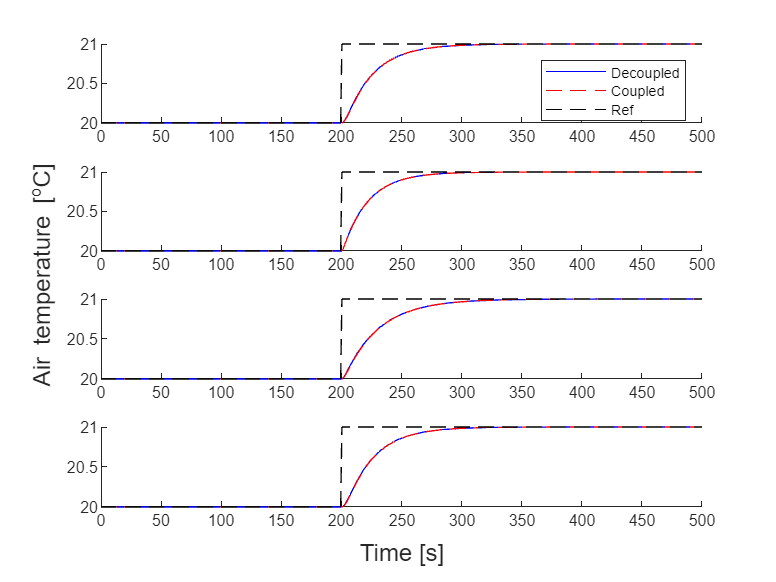

% % % save('SOF_Performance2min.mat','param')
[~,res] = util.SimulateStep(param,"SimulateNonlinearSOFResults_2_min",0,500);

info = stepinfo(res.Ta(:,1),res.time,util.Celsius2Kelvin(21),util.Celsius2Kelvin(20),'SettlingTimeThreshold',0.007);
fprintf('Settling time for SOF is: %f \n', (info.SettlingTime - 200));

Settling time for SOF is: 120.836759 
